## Тест1

Точное решение: u(x,t) = x^3 + t^2

resh = @(x,t)(x.^3+t.^2);
h = 1e-2;
a = 1;
k = 1;
tau = 1e-3;
T = 0.5;
f = @(x,t)(- 2*x.^2+3*t.^3+x*t);
mu = @(x) x.^3;
mu_1 = @(t) t.^2;
mu_2 = @(t) a^3 + t.^2;
tic;
u_1 = ROS0(h, a, tau, T, mu, mu_1, mu_2, k, f);
t_1 = toc

t_1 =    0.021224800000000


tic;
u_2 = CROS(h, a, tau, T, mu, mu_1, mu_2, k, f);
t_2 = toc

t_2 =    0.287785500000000


График точного решения:

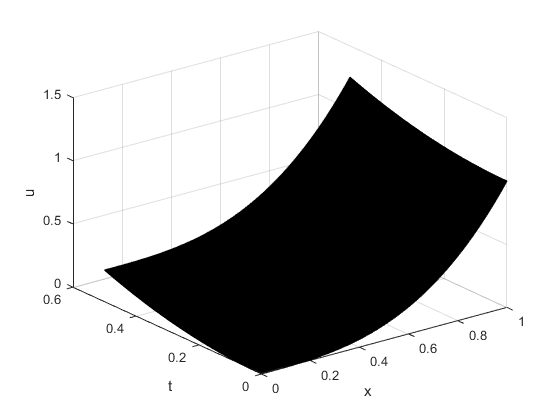

[x,t, u_toch] = tochn(a,T,tau,h,resh);
surf(x,t,u_toch);
xlabel('x');
ylabel('t');
zlabel('u');

График численного решения явным методом: 

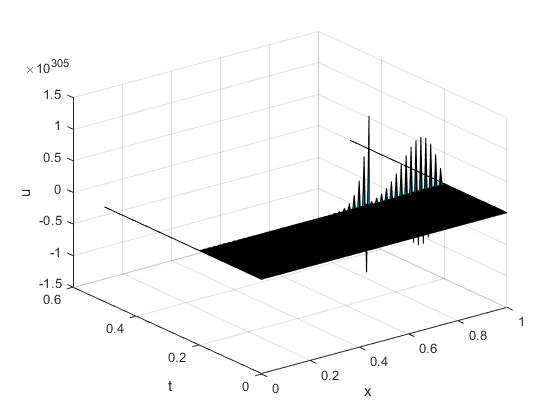

surf(x,t,u_1);
xlabel('x');
ylabel('t');
zlabel('u');

График численного решения неявным методом: 

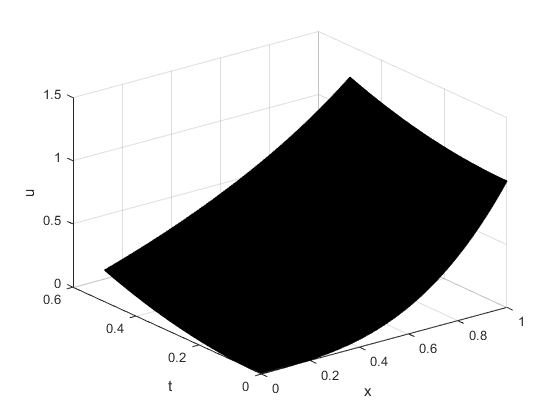

surf(x,t,u_2);
xlabel('x');
ylabel('t');
zlabel('u');

d_1 = u_1 - u_toch;
d_2 = u_2 - u_toch;

Макимальное отклонение явного метода и график откланения:

max(max(abs(d_1)))

ans =    Inf


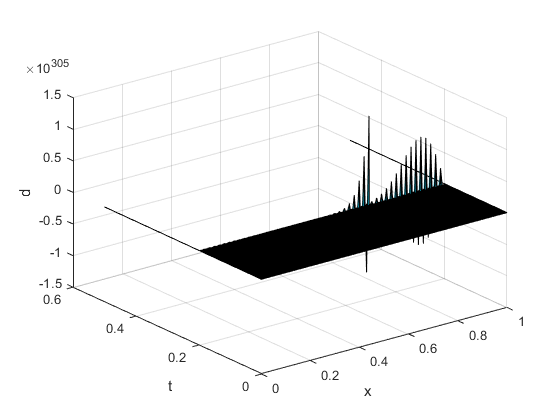

surf(x,t,d_1);
xlabel('x');
ylabel('t');
zlabel('d');

Макимальное отклонение неявного метода и график откланения:

max(max(abs(d_2)))

ans =    0.260738204259402


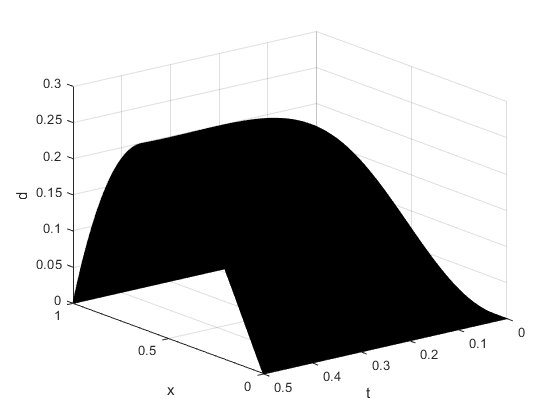

surf(x,t,d_2);
xlabel('x');
ylabel('t');
zlabel('d');

view([231.94409 22.48562])

## Тест 2

Точное решение: u(x,t) = x^3 + t^3

resh = @(x,t)(sin(t - 3).*cos(x/2));
h = 1e-2;
a = 1;
k = 1;
tau = 1e-3;
T = 0.5;
f = @(x,t)(0.25*cos(x/2).*(cos(t -3) + 2*sin(t-3)));
mu = @(x)(sin(-3)*cos(x/2));
mu_1 = @(t) sin(t-3);
mu_2 = @(t) sin(t-3)*cos(a/2);
tic;
u_1 = ROS0(h, a, tau, T, mu, mu_1, mu_2, k, f);
t_1 = toc

t_1 =    0.018836700000000


tic;
u_2 = CROS(h, a, tau, T, mu, mu_1, mu_2, k, f);
t_2 = toc

t_2 =    0.670255800000000


График точного решения:

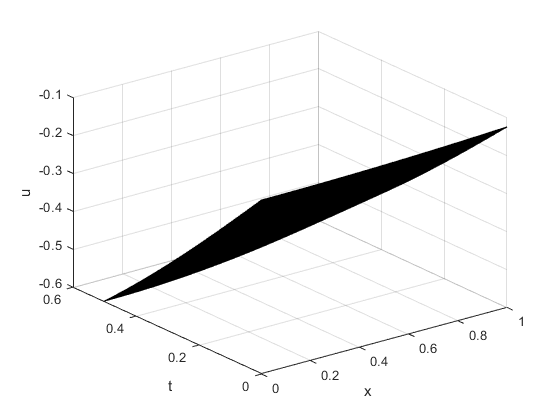

[x,t, u_toch] = tochn(a,T,tau,h,resh);
surf(x,t,u_toch);
xlabel('x');
ylabel('t');
zlabel('u');

График численного решения явным методом: 

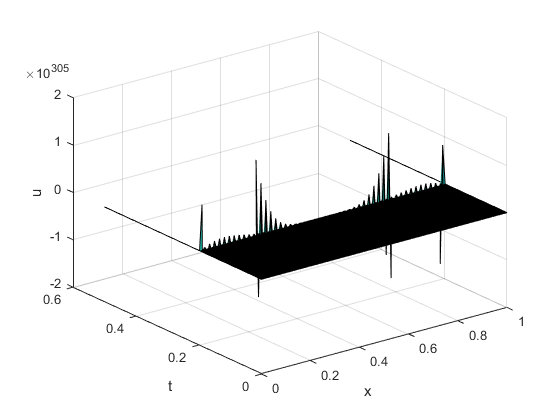

surf(x,t,u_1);
xlabel('x');
ylabel('t');
zlabel('u');

График численного решения неявным методом: 

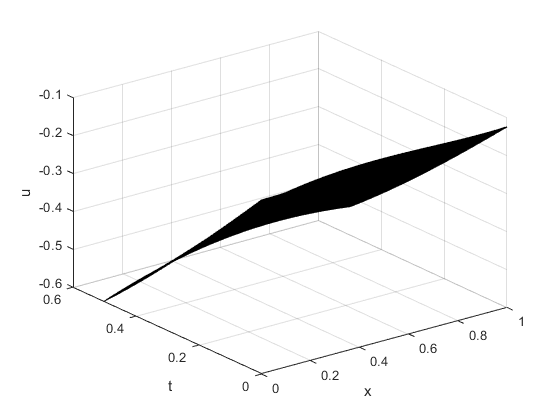

surf(x,t,u_2);
xlabel('x');
ylabel('t');
zlabel('u');

d_1 = u_1 - u_toch;
d_2 = u_2 - u_toch;

Макимальное отклонение явного метода и график откланения:

max(max(abs(d_1)))

ans =    Inf


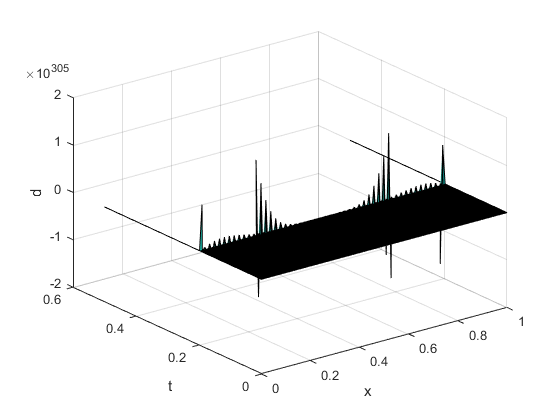

surf(x,t,d_1);
xlabel('x');
ylabel('t');
zlabel('d');

Макимальное отклонение неявного метода и график откланения:

max(max(abs(d_2)))

ans =    0.070522592609777


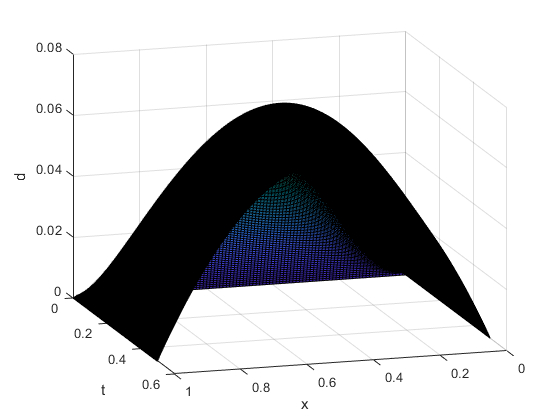

surf(x,t,d_2);
xlabel('x');
ylabel('t');
zlabel('d');

view([-196.91214 18.04467])